# **Techniques to speed up MATLAB code**

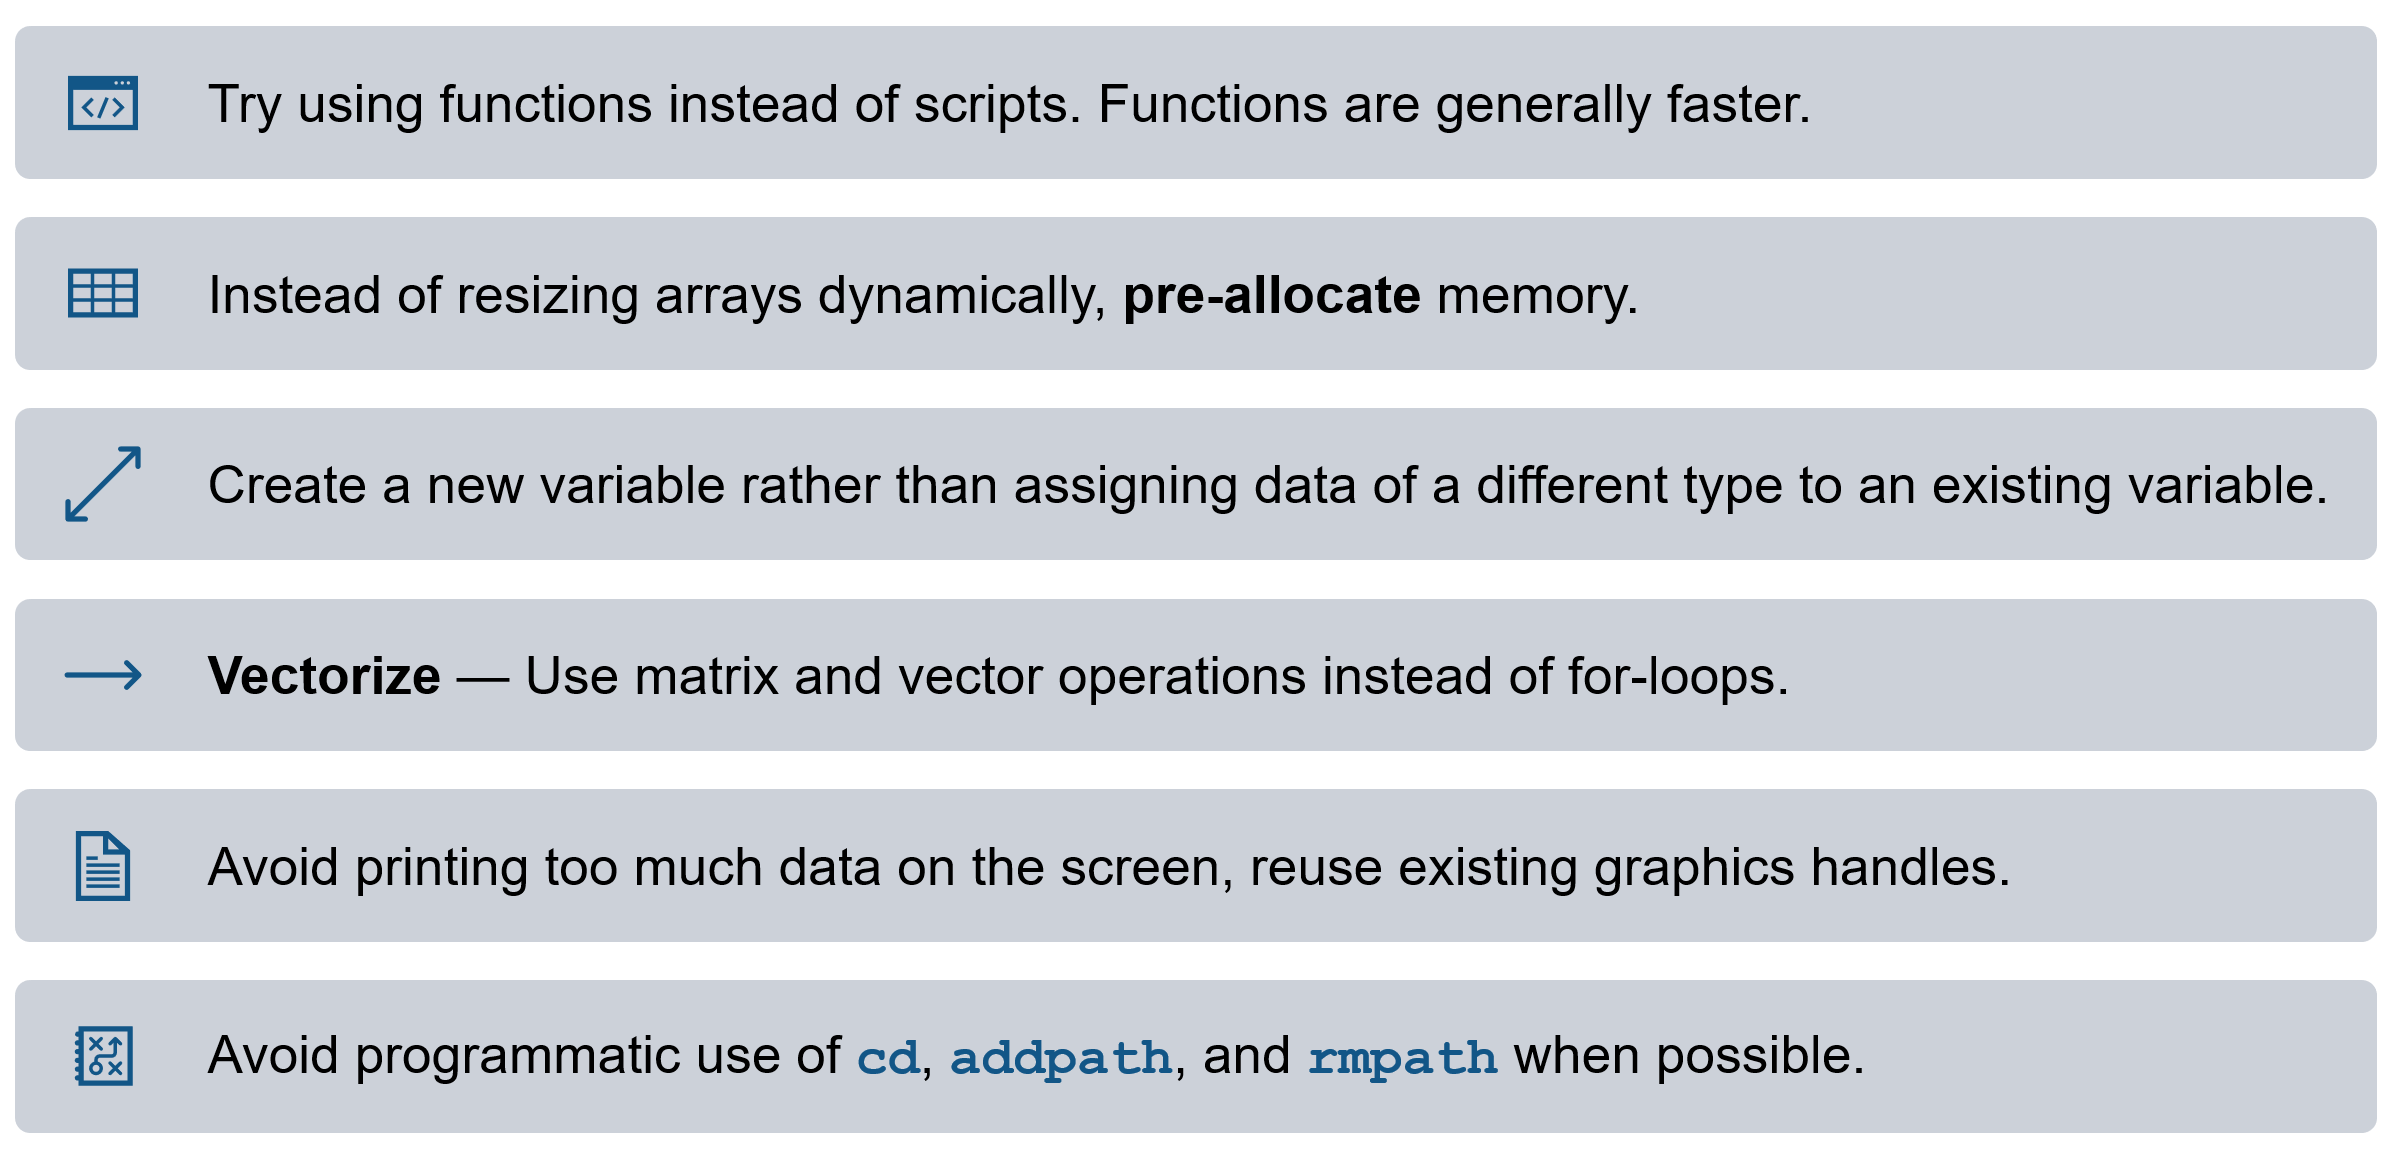

**MATLAB code analyzer **

The Code Analyzer in the MATLAB Editor checks your code while you are writing it. The Code Analyzer identifies potential problems and recommends modifications to maximize performance.

tic
i = 0;
y = 0;
for t = 0:.01:1e4
    i = i + 1;
    y(i) = sin(t);
end
plainTime = toc

plainTime = 0.1607

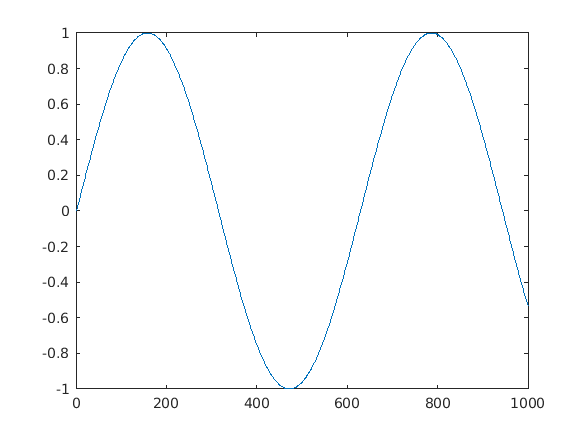

figure;plot(y(1:1e3))

**Memory preallocation **

With preallocation, you initialize an array using the final size required for that array. Preallocation helps you avoid dynamically resizing arrays, particularly when code contains for and while loops.

tic
i = 0;
y = zeros(size(0:.01:1e4));
for t = 0:.01:1e4
    i = i + 1;
    y(i) = sin(t);
end
prealTime = toc

prealTime = 0.0537

percentDifference = plainTime/prealTime;
sprintf('Speedup factor of %f',(percentDifference))

ans = 'Speedup factor of 2.991512'

**Vectorization**

Vectorization is the process of converting code from using loops to using matrix and vector operations.

tic
t = 0:.01:1e4;
y = sin(t);
vecTime = toc

vecTime = 0.0253

percentDifference = plainTime/vecTime;
sprintf('Speedup factor of %f',(percentDifference))

ans = 'Speedup factor of 6.347038'

### Profiler 

The Profiler shows where your code is spending its time. It provides a report summarizing the execution of your code, including the list of all functions called, the number of times each function was called, and the total time spent within each function . The Profiler also provides timing information about each function, such as which lines of code use the most processing time. This lets you find bottlenecks and streamline your serial code. 

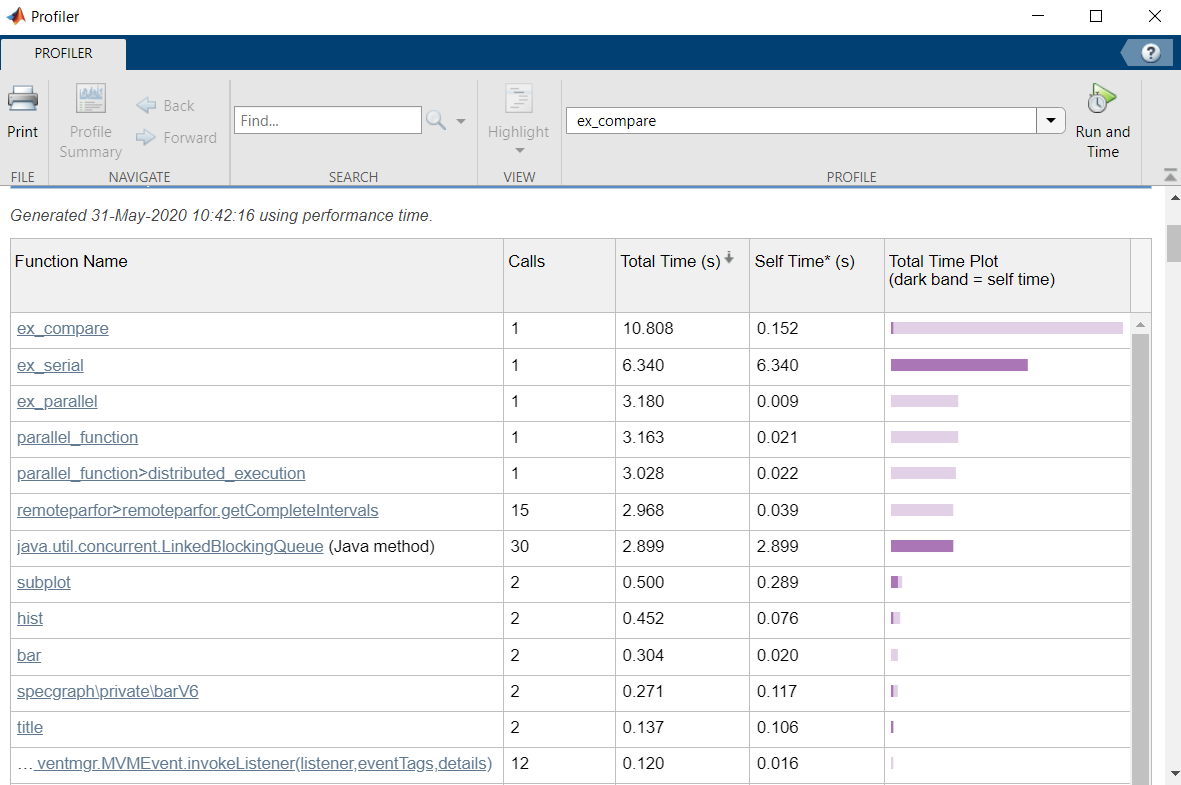

### Mex file generation 

MATLAB is an interpreted language --> every lines of code needs to be translated into machine code which is then executed. Over the years, several optimizations have been introduced and enhanced. However, there is still an overhead associated with the execution of each line of code. If the execution time of a line is very small, this overhead can become significant compared to the execution time and thus slow down code execution when compared to equivalent implementation in other languages. 

The strength of MATLAB is to work efficiently with potentially large vectors and matrices. However, there are cases when vectorization is not possible or would be very time-consuming. In such cases, it is beneficial to create compiled code from MATLAB code using MATLAB® Coder™. While MATLAB Coder offers several options beyond that, for the purpose of accelerating MATLAB code within MATLAB it is sufficient to generate a MEX (MATLAB Executable) file. This is basically C code with a wrapper that lets you run that code directly from MATLAB.

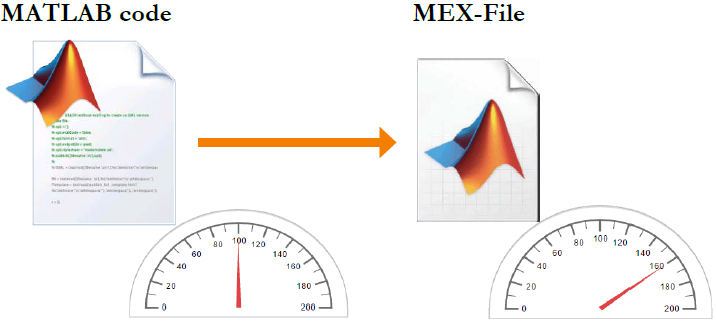

**1. Preparing MATLAB Code for Code Generation**

you should first examine your MATLAB code and make sure it is compliant with code generation standards. The first step in this process is adding the compilation directive 

to the first line of your MATLAB code. This is a meta comment to indicate that you intend to generate code for the MATLAB algorithm. Adding this directive instructs the MATLAB Code Analyzer (which gives tooltips as indicated by the bar on the right of the MATLAB Editor) to help you diagnose and correct violations that would result in errors during code generation.

edit runBirthday

Add %#codegen to the first line and observe code generation errors indicated by MATLAB Code Analyzer. Add the preallocation code:

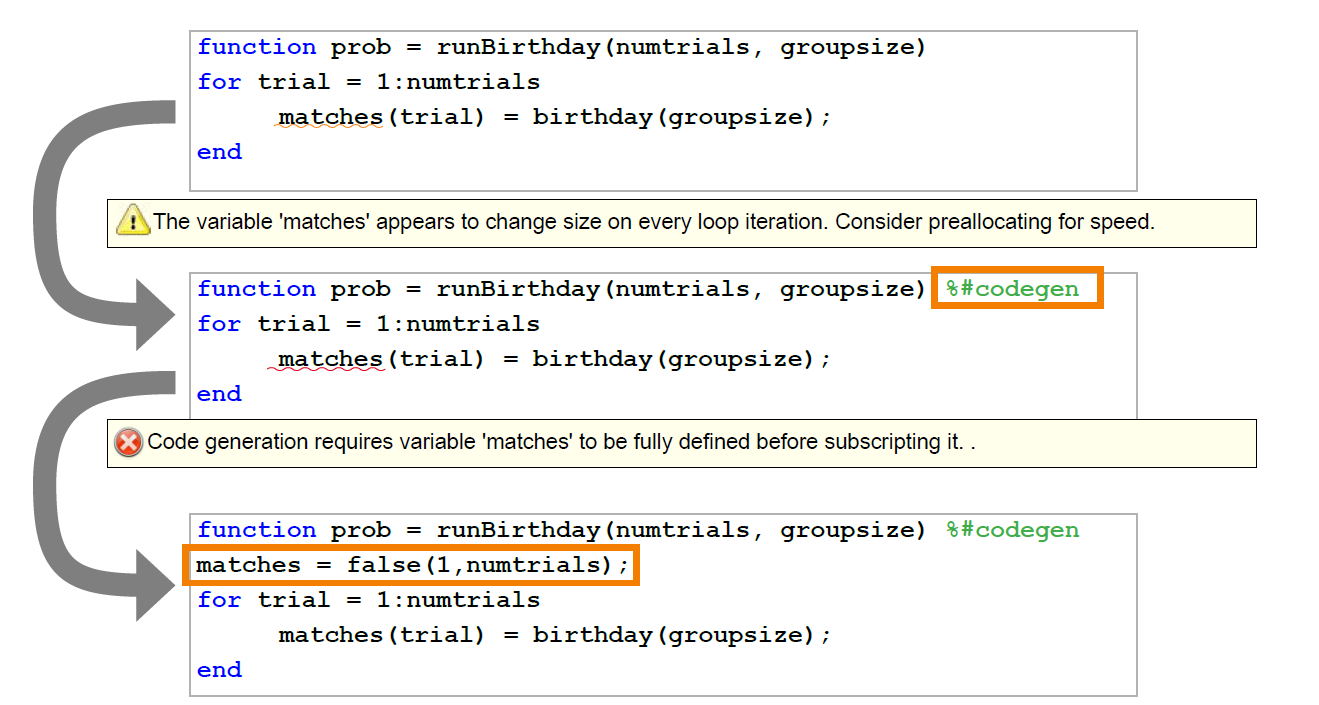

**2. Creating a MATLAB Coder™ Project**

You can use MATLAB Coder app interface to specify all the code generation options. To set up a MATLAB Coder project

coder runBirthday

Alternatively you can open a new MATLAB Coder project by clicking the MATLAB Coder icon in the Apps tab of MATLAB toolstrip.

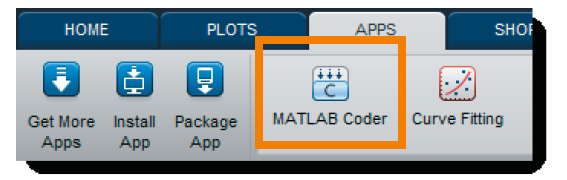

**3. Verifying Generated Code**

You can use the generated MEX-file to verify that the generated (and compiled) code yields the same result as the original MATLAB function and to compare the execution time. 

To run the generated MEX-file using the same input you used for the original MATLAB function and verify the result

1. Run the original MATLAB function

tic, prob1 = runBirthday(1e5, 30), mlTime = toc

prob1 = 0.7066

mlTime = 2.3517

2. Run the generated MEX-function

tic, prob2 = runBirthday_mex(1e5, 30), mexTime = toc

prob2 = 0.7066

mexTime = 0.3343

3. Compute the speedup

percentDifference = mlTime/mexTime;
sprintf('Speedup factor of %f',(percentDifference))

ans = 'Speedup factor of 7.034121'